%Retrieve Data from Computer
testData = readtable("Results.csv")

testData = 132×16 table
      Time      Temperature    Pressure    Altitude    AccelX       AccelY        AccelZ        MagX       MagY        MagZ        GyroX        GyroY         GyroZ       GPSFix     GPSLat    GPSLong
    ________    ___________    ________    ________    _______    __________    __________    ________    _______    ________    _________    __________    _________    ________    ______    _______

    0.051288      23.688        9

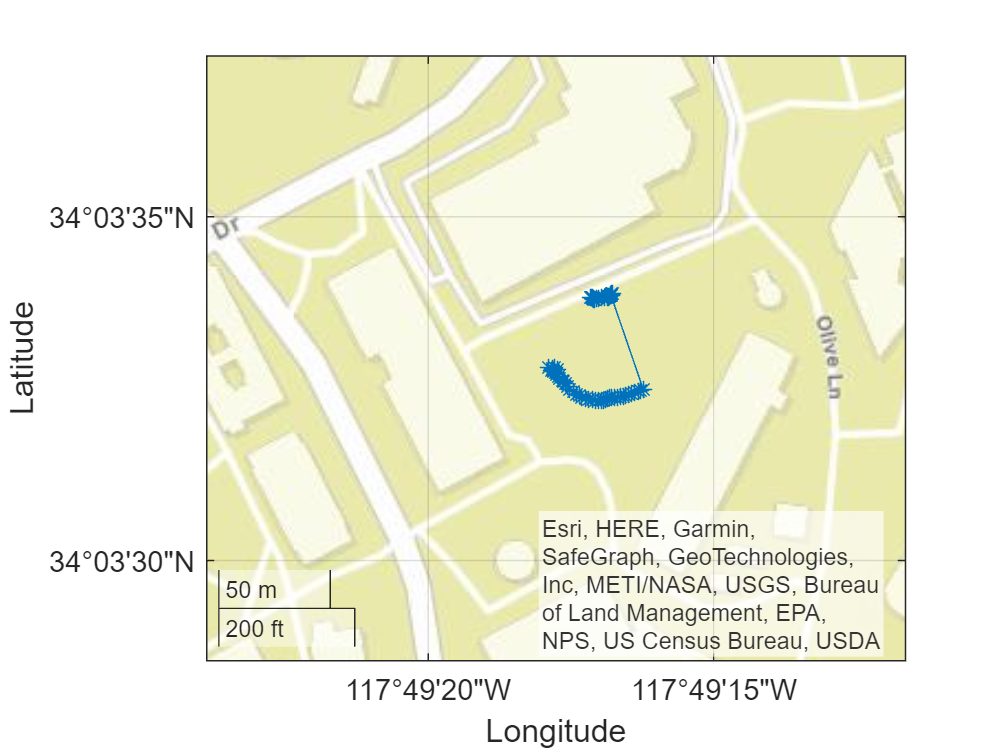


%Extract Readings from Data and add Corrections
time = testData.Time;
temperatureRead = testData.Temperature';
altitudeRead = testData.Altitude';
xAccelRead = testData.AccelX' - 1.20;
yAccelRead = testData.AccelY' - 0.41;
zAccelRead = -testData.AccelZ' - 9.81;
xMagRead = testData.MagX';
yMagRead = testData.MagY';
zMagRead = testData.MagZ';
xGyroRead = testData.GyroX' + 0.004;
yGyroRead = testData.GyroY' + 0.019;
zGyroRead = testData.GyroZ - 0.074;
GPSLatRead = testData.GPSLat';
GPSLongRead = testData.GPSLong';

%Time Length
interval = height(testData);

%Initialize calculation matrices
xVel = zeros(1, interval);
yVel = zeros(1, interval);
zVel = zeros(1, interval);
Airs = zeros(1, interval);
Roll = zeros(1, interval);
Pitch = zeros(1, interval);
Yaw = zeros(1, interval);
Slip = zeros(1, interval);
Climb = zeros(1, interval);
Head = zeros(1, interval);
Alt = zeros(1, interval);


% Loop through the time interval
for i = 2:interval

    % Get the time delta between this point and last
    deltaTime = time(i)-time(i-1);

    % Calculate velocities
    xVel(i) = xVel(i-1) + xAccelRead(i)*deltaTime;
    yVel(i) = yVel(i-1) + yAccelRead(i)*deltaTime;
    zVel(i) = zVel(i-1) + zAccelRead(i)*deltaTime;

    % Airspeed (it's really groundspeed plus vertical speed)
    Airs(i) = convvel(sqrt(xVel(i)^2 + yVel(i)^2 + zVel(i)^2),'m/s','kts');

    % Calculate roll, pitch, and yaw
    Roll(i) = Roll(i-1) + xGyroRead(i)*(time(i)-time(i-1));
    Pitch(i) = Pitch(i-1) + yGyroRead(i)*(time(i)-time(i-1));
    Yaw(i) = Yaw(i-1) + zGyroRead(i);

    % Slip and climb
    Slip(i) = 1/(2*pi)*convang(atan(zGyroRead(i)*sqrt(xVel(i)^2 + yVel(i)^2 + zVel(i)^2)/9.81 - Roll(i)),'rad','deg');
    Climb(i) = convvel(zVel(i),'m/s','ft/min');

    % Heading and altitude
    Head(i) = rad2deg(atan(yMagRead(i)/xMagRead(i)));
    Alt(i) = convlength(altitudeRead(i),'m','ft');
end

% Convert to degrees
Roll = rad2deg(Roll);
Pitch = rad2deg(Pitch);
Yaw = rad2deg(Yaw);

% Prepared the data so taht it can be read by Simulink
Horizon = [time Roll' Pitch'];
Airspeed = [time Airs'];
ClimbRate = [time Climb'];
Turn = [time Slip' Yaw'];
Heading = [time Head'];
Altitude = [time Alt'];
Temperature = [time temperatureRead'];

% Plot GPS data
geoplot(GPSLatRead,GPSLongRead,'-*')
% Set the limits to the CPP Engineering Quad
geolimits([34.0584,34.0599],[-117.8233,-117.8199])
geobasemap streets